# Group 17-DTMC

Question:

The Gadgets-R-Us company has a manufacturing setup consisting of two distinct machines, each producing one component per hour. Each component can be tested instantly to be identified as defective or nondefective. Let *a*i be the probability that a component produced by machine *i* is nondefective, *i*= 1, 2. (Obviously 1 - *a**i* is the probability that a component produced by machine *i* is defective.) The defective components are discarded and the nondefective components produced by each machine are stored in two separate bins. When a component is present in each bin, the two are instantly assembled together and shipped out. Each bin can hold at most two components. When a bin is full, the corresponding machine is turned off. It is turned on again when the bin has space for at least one component. 

1.Model this system by a DTMC.

2.Generate the 15 realization of Chain.

3.Compute limiting distribution.

#### States Assumed in Solving the problem:

A- Bin 1 and Bin 2 BOTH have 0 components.

B- Bin1 has 1 component while Bin2 has 0.

C- Bin1 has 0 components while Bin2 has 1.

D- Machine 2 is stopped, Bin1 has 0 components while Bin2 has 2.

E- Machine 1 is stopped, Bin1 has 2 components while Bin2 has 0.

## Setting Given probabilities

- Given a1,a2:

a1=0.4;%Change given a1,a2 probabilities here
a2=0.8;
disp('a1 is:')

a1 is:


disp(a1)

    0.4000



disp('a2 is:')

a2 is:


disp(a2)

    0.8000



        2.Setting transition Probabilities:

p11=a1*a2;
p10=a1*(1-a2);
p01=(1-a1)*a2;
p00=(1-a1)*(1-a2);
p1x=a1;
px1=a2;
p0x=1-a1;
px0=1-a2;

        3. Transition Matrix:

disp('The Transition Matrix(T) is:')

The Transition Matrix(T) is:


T=[p00+p11,p10,p01,0,0;p01,p00+p11,0,0,p10;p10,0,p00+p11,p01,0;0,0,p1x,p0x,0;0,px1,0,0,px0];
disp(T)

    0.4400    0.0800    0.4800         0         0
    0.4800    0.4400         0         0    0.0800
    0.0800         0    0.4400    0.4800         0
         0         0    0.4000    0.6000         0
         0    0.8000         0         0    0.2000



## Graphing Markov Chain

mc=dtmc(T,'Statenames',["A","B","C","D","E"])

mc =   dtmc with properties:

             P: [5×5 double]
    StateNames: ["A"    "B"    "C"    "D"    "E"]
     NumStates: 5


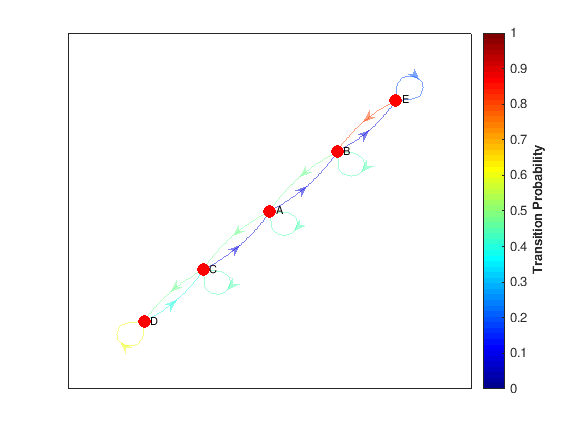

figure
graphplot(mc,'Coloredges',true)

## Computing n realizations

n=15;%Change n here to change number of realizations
disp('Now generating 15 realizations')

Now generating 15 realizations


cA=cumsum(T(1,:));
cB=cumsum(T(2,:));
cC=cumsum(T(3,:));
cD=cumsum(T(4,:));
cE=cumsum(T(5,:));
cT=[cA;cB;cC;cD;cE];
disp('CDF matrix is:')

CDF matrix is:


disp(cT)

    0.4400    0.5200    1.0000    1.0000    1.0000
    0.4800    0.9200    0.9200    0.9200    1.0000
    0.0800    0.0800    0.5200    1.0000    1.0000
         0         0    0.4000    1.0000    1.0000
         0    0.8000    0.8000    0.8000    1.0000



%Realizations code:
for i=(1:n)
    if i==1 
        %Selecting Initial State
        x=rand;
        g1=0.2;
        g2=0.4;
        g3=0.6;
        g4=0.8;
        g5=1;
        if x<g1
            disp('INITIAL STATE SELECTED IS A')
            State=1;
        end
        if x>g1 && x<g2
            disp('INITIAL STATE SELECTED IS B')
            State=2;
        end
        if x>g2 && x<g3
            disp('INITIAL STATE SELECTED IS C')
            State=3;
        end
        if x>g3&& x<g4
            disp('INITIAL STATE SELECTED IS D')
            State=4;
        end
        if x>g4 && x<g5
            disp('INITIAL STATE SELECTED IS E')
            State=5;
        end
        %disp(State)
    else
    %Other Realizations:
         fprintf('%ith Realization:',i)
         x=rand;
         g1=cT(State,1);
         g2=cT(State,2);
         g3=cT(State,3);
         g4=cT(State,4);
         g5=cT(State,5);
         if x<g1
            disp('STATE IS A')
            State=0;
        end
        if x>g1 && x<g2
            disp('STATE IS B')
            State=1;
        end
        if x>g2 && x<g3
            disp('STATE IS C')
            State=2;
        end
        if x>g3&& x<g4
            disp('STATE IS D')
            State=3;
        end
        if x>g4 && x<g5
            disp('STATE IS E')
            State=4;
        end
    end   
   
end

INITIAL STATE SELECTED IS E


2th Realization:

STATE IS B


3th Realization:

STATE IS A


## Computing limiting distribution